# Self-consistent Method

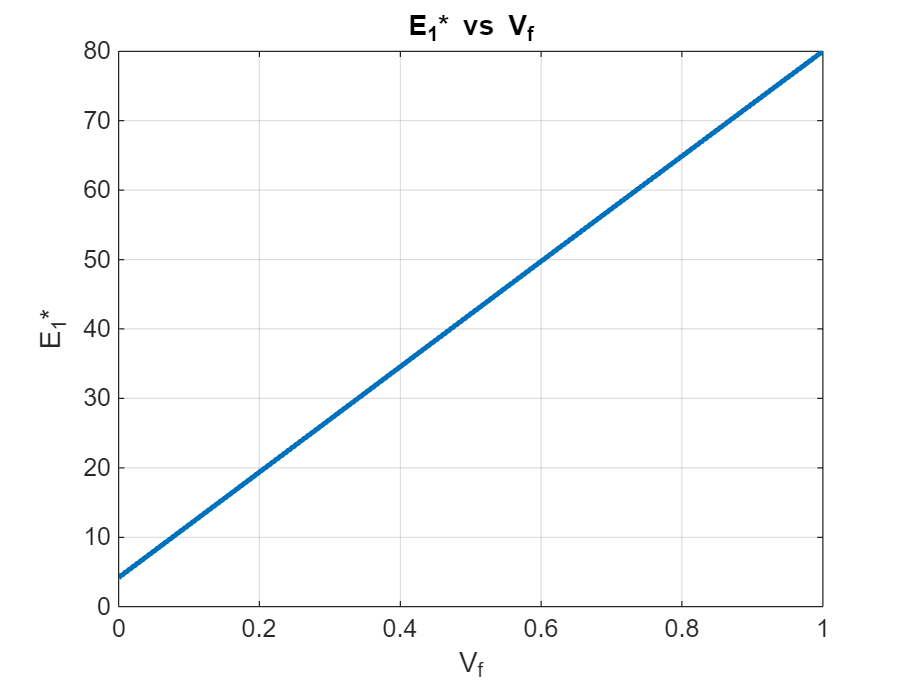

clc;clear;
Vf_val = linspace(0, 1, 101);
Vm_val = 1 - Vf_val;

E_f = 80;
G_f = 33.33;
v_f = 0.2;

S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

E_m = 4.2;
v_m = 0.34;
G_m = E_m/(2*(1+v_m));

S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

% fiber
syms n_f m_f k_f l_f p_f
eqn1 = n_f == C_f(1,1);
eqn2 = l_f == C_f(1,2);
eqn3 = k_f + m_f == C_f(2,2);
eqn4 = m_f == C_f(4,4);
eqn5 = p_f == C_f(5,5);

fiber = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_f,l_f,k_f,m_f,p_f]);
n_f = double(fiber.n_f);
m_f = double(fiber.m_f);
k_f = double(fiber.k_f);
l_f = double(fiber.l_f);
p_f = double(fiber.p_f);

% matrix
syms n_m m_m k_m l_m p_m
eqn1 = n_m == C_m(1,1);
eqn2 = l_m == C_m(1,2);
eqn3 = k_m + m_m == C_m(2,2);
eqn4 = m_m == C_m(4,4);
eqn5 = p_m == C_m(5,5);

matrix = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_m,l_m,k_m,m_m,p_m]);
n_m = double(matrix.n_m);
m_m = double(matrix.m_m);
k_m = double(matrix.k_m);
l_m = double(matrix.l_m);
p_m = double(matrix.p_m);

% Storage for results
k_c = zeros(size(Vf_val));
m_c = zeros(size(Vf_val));
p_c = zeros(size(Vf_val));


k_c(1) = k_m;
m_c(1) = l_m;
p_c(1) = p_m;

k_c(length(Vf_val)) = k_f;
m_c(length(Vf_val)) = l_f;
p_c(length(Vf_val)) = p_f;

for i = 2:length(Vf_val)-1
    current_Vf = Vf_val(i);
    current_Vm = Vm_val(i);

    syms k_star m_star p_star
    
    eq1 = (current_Vf * k_f) / (k_f + m_star) + (current_Vm * k_m) / (k_m + m_star) == ...
          2 * ((current_Vf * m_m) / (m_m - m_star) + (current_Vm * m_f) / (m_f - m_star));
    
    eq2 = (1 / (2 * p_star)) == (current_Vf / (2 * (p_star - p_m))) + (current_Vm / (2 * (p_star - p_f)));
    
    eq3 = (1 / (k_star + m_star)) == (current_Vf / (k_f + m_star)) + (current_Vm / (k_m + m_star));

    sol = solve([eq1, eq2, eq3], [k_star, m_star, p_star]);
    
    k_star_sol = double(sol.k_star);
    m_star_sol = double(sol.m_star);
    p_star_sol = double(sol.p_star);
    
    approved = find(isreal(k_star_sol) & isreal(m_star_sol) & isreal(p_star_sol) & ...
                     (k_star_sol >= 0) & (m_star_sol >= 0) & (p_star_sol >= 0));

    k_c(i) = k_star_sol(approved(1));
    m_c(i) = m_star_sol(approved(1));
    p_c(i) = p_star_sol(approved(1));
end

l_c = zeros(size(Vf_val));
n_c = zeros(size(Vf_val));

l_c(1) = l_m;
l_c(end) = l_f;

n_c(1) = n_m;
n_c(end) = n_f;

for i = 2:length(Vf_val)-1
    current_Vf = Vf_val(i);
    current_Vm = Vm_val(i);

    k_star = k_c(i);
    m_star = m_c(i);

    A = (k_f - k_m) / (l_f - l_m);

    l_star = l_f + (k_star - k_f)/A;

    n_star = (l_star - current_Vf * l_f - current_Vm * l_m)/A + ...
             current_Vf * n_f + current_Vm * n_m;

    l_c(i) = l_star;
    n_c(i) = n_star;
end

C_c_all = cell(size(Vf_val));
S_c_all = cell(size(Vf_val));

for i = 1:length(Vf_val)

    C_c = [n_c(i), l_c(i), l_c(i), 0,      0,      0;
           l_c(i), k_c(i)+m_c(i), k_c(i)-m_c(i), 0, 0, 0;
           l_c(i), k_c(i)-m_c(i), k_c(i)+m_c(i), 0, 0, 0;
           0,      0,      0,      m_c(i), 0,      0;
           0,      0,      0,      0,      p_c(i), 0;
           0,      0,      0,      0,      0,      p_c(i)];

    S_c = inv(C_c);

    C_c_all{i} = C_c;
    S_c_all{i} = S_c;
end

E1_c_val   = zeros(size(Vf_val));
E2_c_val   = zeros(size(Vf_val));
v12_c_val  = zeros(size(Vf_val));
v23_c_val  = zeros(size(Vf_val));
G12_c_val  = zeros(size(Vf_val));
G23_c_val  = zeros(size(Vf_val));

E1_c_val(1)  = E_m; 
E2_c_val(1)  = E_m; 
v12_c_val(1) = v_m;
v23_c_val(1) = v_m;
G12_c_val(1) = G_m;
G23_c_val(1) = G_m; 

E1_c_val(length(Vf_val))  = E_f; 
E2_c_val(length(Vf_val))  = E_f; 
v12_c_val(length(Vf_val)) = v_f;
v23_c_val(length(Vf_val)) = v_f;
G12_c_val(length(Vf_val)) = G_f;
G23_c_val(length(Vf_val)) = G_f; 

for i = 2:length(Vf_val)-1
    S = S_c_all{i};

    E1_c_val(i)  = 1 / S(1,1);
    E2_c_val(i)  = 1 / S(2,2);
    v12_c_val(i) = -S(1,2) * E1_c_val(i);
    v23_c_val(i) = -S(2,3) * E2_c_val(i);
    G12_c_val(i) = 1 / S(5,5);
    G23_c_val(i) = 1 / S(4,4);
end

% Plotting
figure;
plot(Vf_val, E1_c_val, 'LineWidth', 2);
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
grid on;

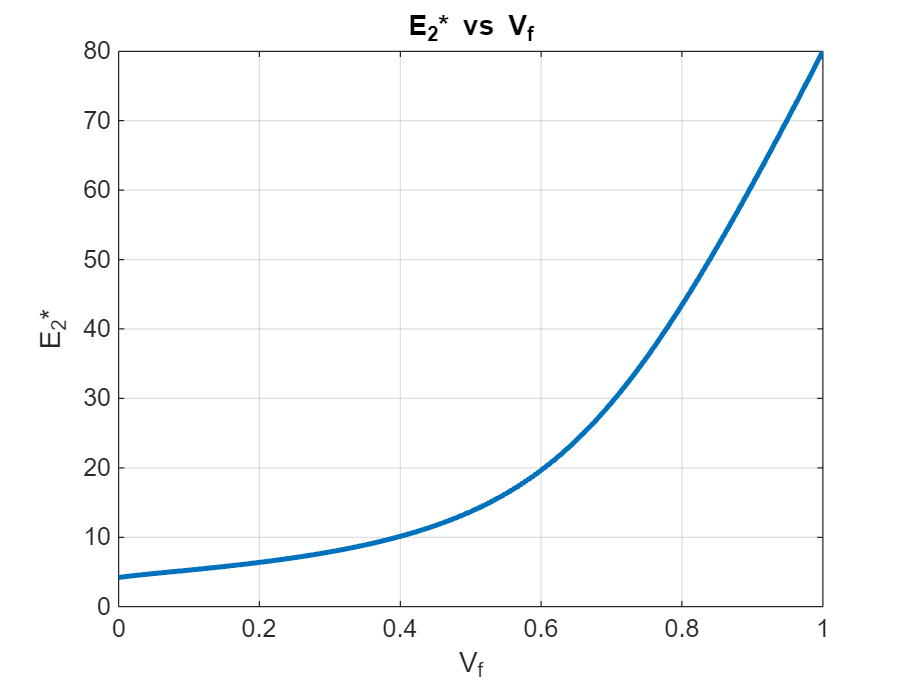


figure;
plot(Vf_val, E2_c_val, 'LineWidth', 2);
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
grid on;

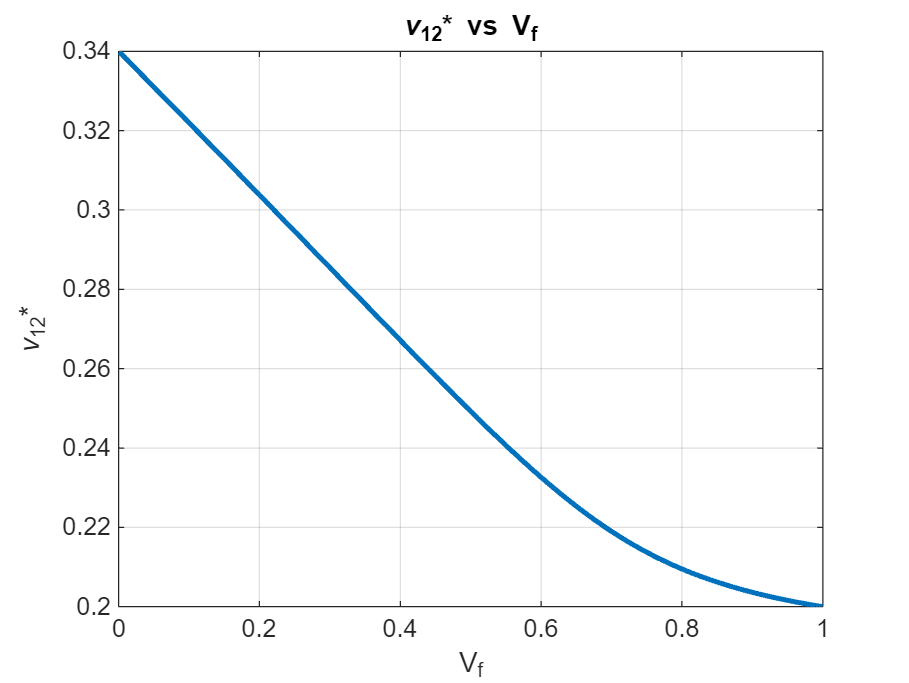


figure;
plot(Vf_val, v12_c_val, 'LineWidth', 2);
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
grid on;

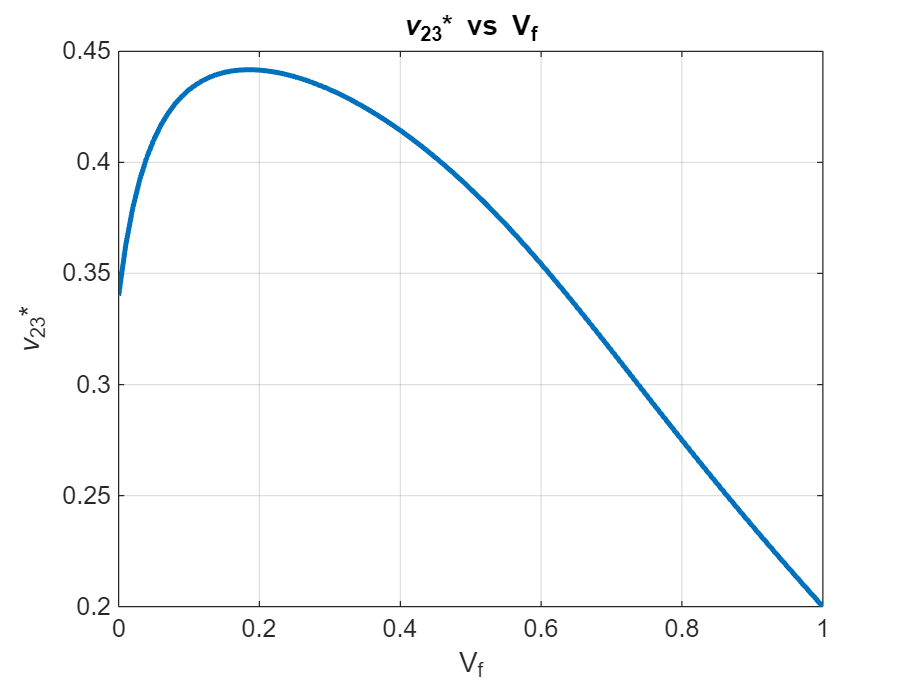


figure;
plot(Vf_val, v23_c_val, 'LineWidth', 2);
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
grid on;

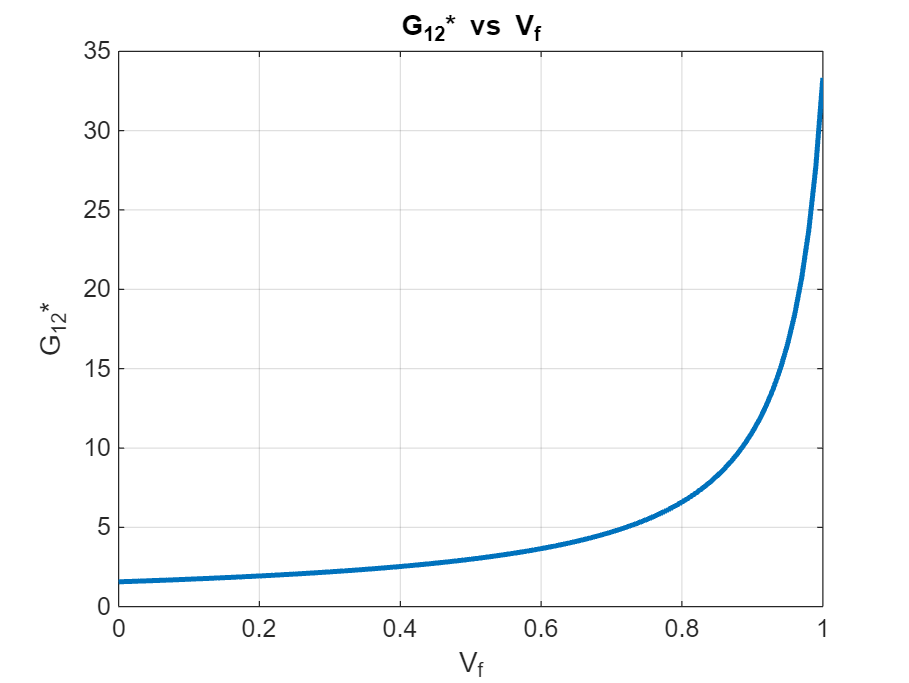


figure;
plot(Vf_val, G12_c_val, 'LineWidth', 2);
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
grid on;

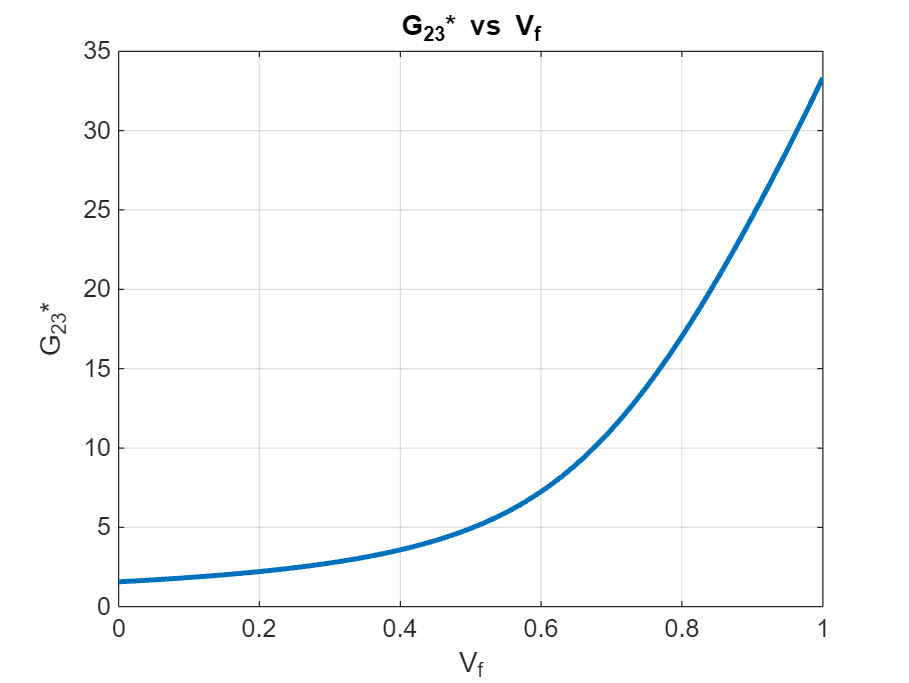


figure;
plot(Vf_val, G23_c_val, 'LineWidth', 2);
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
grid on;